## ECI

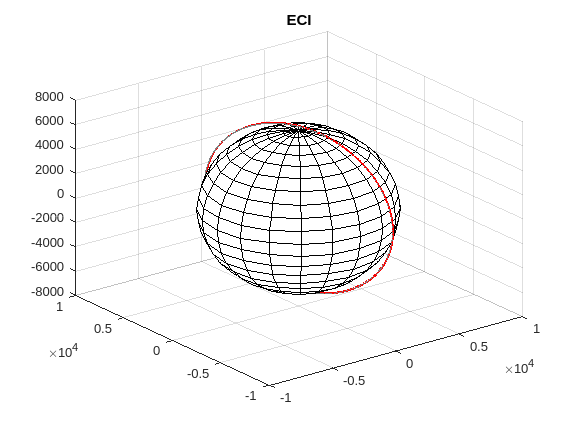

ECI = importdata("ECI.txt");

figure

plot3(ECI(:,1), ECI(:,2), ECI(:,3),'LineStyle','--','LineWidth',0.5,'color',[.5 .5 .5])
hold on

% Initialize the plot
h = plot3(ECI(1, 1), ECI(1, 2), ECI(1, 3),'LineWidth',1.5,'color','r');
grid on;
title('ECI');
hold on
xlim([-1e4 1e4]);
ylim([-1e4 1e4]);
zlim([-8e3 8e3]);

% Make unit sphere
[x1,y1,z1] = sphere;
% Scale to desire radius.
radius = 6378;
x2 = x1 * radius;
y2 = y1 * radius;
z2 = z1 * radius;

% Plot as surface.
surf(x2, y2, z2, 'FaceColor', [1, 1, 1], 'EdgeColor', [0, 0, 0]);


% Run for simulation
for i = 2:length(ECI(:, 1))
    % Update the plot data
    set(h, 'XData', ECI(1:i, 1), 'YData', ECI(1:i, 2), 'ZData', ECI(1:i, 3));

    % Pause for a short duration to control animation speed
    pause(0.01); % Adjust the pause duration as needed
end



## ECEF

ECEF = importdata("ECEF.txt");

figure

plot3(ECEF(:,1), ECEF(:,2), ECEF(:,3),'LineStyle','--','LineWidth',0.5,'color',[.5 .5 .5])
hold on

% Initialize the plot
h = plot3(ECEF(1, 1), ECEF(1, 2), ECEF(1, 3),'LineWidth',1.5,'color','r');
grid on;
title('ECEF');
hold on

% Make unit sphere
[x1,y1,z1] = sphere;
% Scale to desire radius.
radius = 6378;
x2 = x1 * radius;
y2 = y1 * radius;
z2 = z1 * radius;

xlim([-1e4 1e4]);
ylim([-1e4 1e4]);
zlim([-8e3 8e3]);

% Plot as surface.
earth = surf(x2,y2,z2);

set(earth, 'FaceColor', [1 1 1],'EdgeColor',[0 0 0]);

% Run for simulation
for i = 2:length(ECEF(:, 1))
    % Update the plot data
    set(h, 'XData', ECEF(1:i, 1), 'YData', ECEF(1:i, 2), 'ZData', ECEF(1:i, 3));

    % Pause for a short duration to control animation speed
    pause(0.01); % Adjust the pause duration as needed
end



## Groundtrack

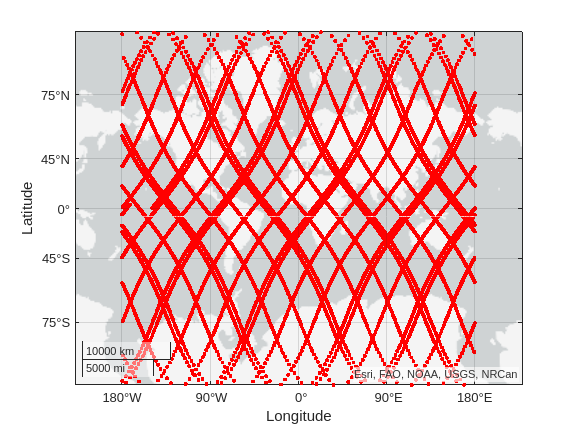

GEO = importdata("GEO.txt");
figure
% for i = 2:length(GEO(:, 1))
%     % Update the plot data
%     geoscatter(GEO(1:i,2), GEO(1:i,1),'Marker','.',"MarkerEdgeColor",'r', "MarkerFaceColor",'r');
% 
%     % Pause for a short duration to control animation speed
%     pause(0.01); % Adjust the pause duration as needed
% end

geoscatter(GEO(:,2),GEO(:,1),'Marker','.',"MarkerEdgeColor",'r', "MarkerFaceColor",'r')


% lla = ecef2lla([ECEF(:,1)*1000 ECEF(:,2)*1000 ECEF(:,3)*1000], 'WGS84');
% geoscatter(lla(:,1), lla(:,2))

